clc;
clear;
close all;

%% 1. 读取数据
FileName = '/Users/ryan/Desktop/continuum robot/force_data/after_processing_data_0816.xlsx';
dataTable = readtable(FileName);

disp(dataTable(1:5,:)); % 显示前5行预览

       Var1         Var2      Var3    Var4     f1_c0      f2_c1     f3_c2    f4_c3    f5_c4    f6_c5    f1_c0_1    f2_c1_1    f3_c2_1    f4_c3_1    f5_c4_1    f6_c5_1    encoder0    encoder1    encoder2    encoder3    encoder4    encoder5    f1_c0_2    f2_c1_2    f3_c2_2    f4_c3_2    f5_c4_2    f6_c5_2                                                                                                                                                                                                                                                                                                              base1                                                                                                                                                                                                                                                                                                              base2    mid1    mid2    mid3    mid4    mid5    mid6    tip    Var38    Var39    Var40


% 获取总的实验数量（减去表头）
num_total_exp = height(dataTable) - 2;

% 提取所有实验的数据
% 驱动力（预设值） (F1, F2, F3, F4, F5, F6)
force_data = dataTable(3:end, 5:10);
force_array = table2array(force_data);

% 驱动力（撞击前，真值） (F1, F2, F3, F4, F5, F6)
before_hit_force_data = dataTable(3:end, 11:16);
before_hit_force_array = table2array(before_hit_force_data);

% 驱动力（撞击后，真值） (F1, F2, F3, F4, F5, F6)
after_hit_force_data = dataTable(3:end, 23:28);
after_hit_force_array = table2array(after_hit_force_data);

% 外力
outer_force_data = dataTable(3:end, 2);
outer_force_array = table2array(outer_force_data);

% 位姿真值数据
position_data_text = dataTable(3:end, 29);
position_text_array = table2array(position_data_text);

% 外部力的方向和高度编码
direction_data = dataTable(3:end, 3);
height_data = dataTable(3:end, 4);

% 2. 批量处理力和位姿数据
% 初始化变量
F_tendon = zeros(num_total_exp, 3);
F_ex = zeros(3, num_total_exp);
P_RealOffset = zeros(3, 9, num_total_exp);

for i = 1:num_total_exp
%    % 计算驱动腱的力 (Tendon Forces)
%    F_tendon(i,:) = [0.00981*force_array(i,1), 0.00981*force_array(i,2), 0.00981*force_array(i,3)];
% 
%    % ---- 【核心修改部分：根据方向编码计算外部力 F_ex】 ----
%    force_magnitude = force_array(i, 4);
%    direction_code = direction_data.Direction_Fz(i);
%    unit_vec = [0; 0; 0]; % 初始化单位向量
% 
%    switch direction_code
%        case 0
%            unit_vec = [0; -1; 0];         % +Y
%        case 1
%            unit_vec = [sind(45); -cosd(45); 0];
%        case 2
%            unit_vec = [1; 0; 0];        % -X
%        case 3
%            unit_vec = [sind(45); cosd(45); 0];
%        case 4
%            unit_vec = [0; 1; 0];        % -Y
%        case 5
%            unit_vec = [-sind(45); cosd(45); 0];
%        case 6
%            unit_vec = [-1; 0; 0];         % +X
%        case 7
%            unit_vec = [-sind(45); -cosd(45); 0];
%        otherwise
%            warning('第 %d 行实验的方向编码 %d 无效，F_ex设为0。', i, direction_code);
%    end
% 
%    F_ex(:, i) = force_magnitude * unit_vec;
% 
   % 解析位姿真值
   P_RealOffset(:,:,i) = get_RealOffset_1S3CT(position_text_array{i});
end

%% 3. 设置模型常量和参数
tendon = 3;
section = 1;
G = 8*0.00981;
D = 0.0006;
I = pi*D^4/64;
L_b = 0;
L_e = 0;
L_a= 0.070;
N_d = 9;
H_list  = linspace(0.0025, 0.0025, section*N_d+1);
kappa = 4;
id = [0, 2, 4, 7, 9];

% 初始位姿
T_offset_0 = repmat(eye(4), 1, 1, 9); % 更简洁的初始化方法

% 定义材料和摩擦系数
E = 1.816e11;
mu = 0;
EI = E * I;

%% 4. 选择多组实验进行批量计算和绘图 (双色系配色方案)

% ---- 步骤1: 在这里挑选你想绘制的10组效果好的实验序号 ----
% % experiments_to_plot = [4, 12, 15, 18, 25, 28, 35, 38, 45, 44, 78, 84, 102, 103, 104]; % 示例序号，请替换成你的
% % num_plots = length(experiments_to_plot);
% =================== 筛选并绘图 ===================

% ---- Step 1: Define Your Filtering Criteria ----
target_column_index = 3;  % excel中要查找的行数%受力方向是"3"，圆盘编号是"4"
target_value = 4;         % 圆盘编号/受力方向
num_plots = 50;    % 获取的组数

% ---- Step 2: Find All Experiments Matching the Criteria ----
% Get the data from your target column, making sure to skip the header row.
column_data = dataTable{3:end, target_column_index};

% 'group_indices' will now hold the row numbers of all experiments where
% the 3rd column is equal to 4. Note that these are indices relative
% to the data portion (e.g., index 1 = row 2 in Excel).
group_indices = find(column_data == target_value);

% ---- Step 3: Randomly Select Experiments from the Group ----
% Check if we found any experiments to plot
if isempty(group_indices)
    error('Filtering Error: No experiments were found where column %d has a value of %d.', target_column_index, target_value);
end

% Check if we have enough experiments to choose from
if length(group_indices) < num_plots
    warning('Found only %d experiments matching the criteria. Plotting all of them.', length(group_indices));
    % If fewer are found than requested, just plot all of them
    experiments_to_plot = group_indices;
else
    % Randomly shuffle the indices of the found experiments
    shuffled_indices = group_indices(randperm(length(group_indices)));
    % Take the first 'num_random_plots' from the shuffled list
    experiments_to_plot = shuffled_indices(1:num_plots);
end

% Display the randomly chosen experiments in the command window
fprintf('Found %d experiments with %d in column %d.\n', length(group_indices), target_value, target_column_index);

Found 566 experiments with 4 in column 3.


fprintf('Randomly selected experiments to plot:\n');

Randomly selected experiments to plot:


disp(sort(experiments_to_plot)'); % Displaying them sorted is easier to read

   372   387   391   412   424   462   471   491   500   501   514   517   524   526   532   621   635   650   697   718   719   723   725   737   739   785   788   790   798   799   801   813   824   853   863   865   867   881   884   889   910   919   932   948   955   961   965   975   991   993



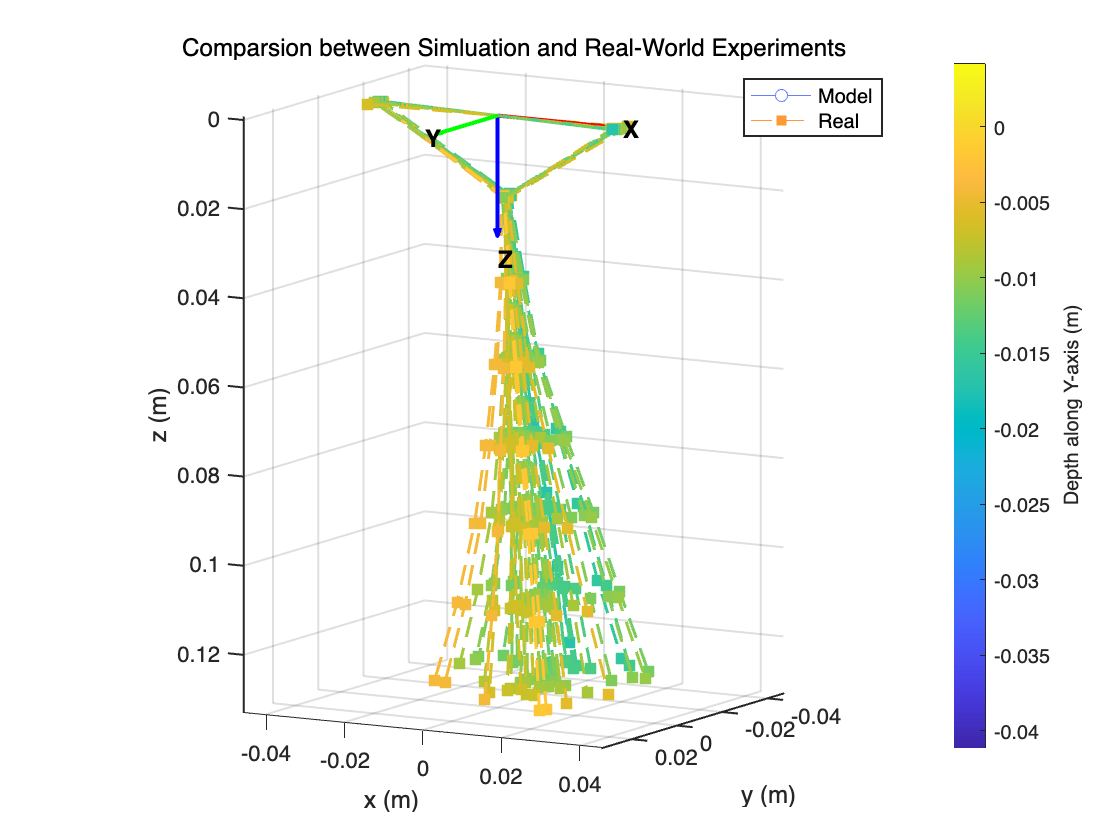

% =================== 筛选并绘图 ===================

% ---- 步骤2: 初始化绘图和误差记录变量 ----
figure('Color', 'white'); % 创建一个白色背景的窗口
hold on;

% ---【配色方案修改】---
% 创建两种颜色梯度：一个蓝色系，一个红色系
% linspace(start, end, n) 创建一个从start到end的n点向量
% 我们用它来改变RGB中的某个通道，从而形成深浅变化
model_colors = [linspace(0.4, 0.4, num_plots)', linspace(0.5, 0.5, num_plots)', ones(num_plots, 1)]; % 从蓝绿色到天蓝色
real_colors  = [ones(num_plots, 1), linspace(0.6, 0.6, num_plots)', linspace(0.2, 0.2, num_plots)']; % 从橙色到深红色

% 初始化用于存储误差表数据的数组
error_list = [];
direction_list = [];
height_list = [];
force1_list = [];
force2_list = [];
force3_list = [];
f_ex_list = [];
% % % ---- 步骤3: 循环计算和绘图 ----
% % for k = 1:num_plots
% %     num_exp = experiments_to_plot(k);
% % 
% %     % 获取当前实验对应的颜色
% %     current_model_color = model_colors(k, :);
% %     current_real_color  = real_colors(k, :);
% % 
% %     % 从已处理好的数据中提取该实验的力
% %     F_tendon_selected = F_tendon(num_exp, :);
% %     F_ex_selected = F_ex(:, num_exp);
% % 
% %     % % % 根据高度编码设置 touch_id
% %     % % height_code = height_data.Height_Fz(num_exp);
% %     % % switch height_code
% %     % %     case 1, touch_id = 5;
% %     % %     case 2, touch_id = 6;
% %     % %     case 3, touch_id = 8;
% %     % %     otherwise, touch_id = 6; % 默认值
% %     % % end
% % 
% %     % 调用你的模型函数进行计算
% %     % % [~, ~, P_CSBCM_offset] = exp_CSBCM_1S3HT_ICIA(T_offset_0, id, tendon, section, F_tendon_selected, F_ex_selected, G, mu, EI, D, H_list, L_a, L_b, N_d, kappa, touch_id);
% %     % % data_CSBCM = P_CSBCM_offset;
% % 
% %     % % % 绘制模型预测结果 (蓝色系, 实线 + 空心圆点)
% %     % % plot3(data_CSBCM(1, :), data_CSBCM(2, :), data_CSBCM(3, :), '-o', ...
% %     % %     'Color', current_model_color, ...
% %     % %     'LineWidth', 1.5, ...
% %     % %     'MarkerSize', 5, ...
% %     % %     'MarkerFaceColor', 'w');
% % 
% %     % 绘制实验真值 (红色系, 虚线 + 实心方块)
% %     plot3(P_RealOffset(1, :, num_exp), P_RealOffset(2, :, num_exp), P_RealOffset(3, :, num_exp), '--s', ...
% %         'Color', current_real_color, ...
% %         'LineWidth', 1, ...
% %         'MarkerSize', 6, ...
% %         'MarkerFaceColor', current_real_color);
% % 
% %     % % % 计算并记录误差
% %     % % data_error = norm(P_RealOffset(1:3,end,num_exp) - data_CSBCM(:,end));
% %     % % error_list(end+1) = data_error;
% %     % % direction_list(end+1) = direction_data.Direction_Fz(num_exp);
% %     % % force1_list(end+1) = F_tendon_selected(1,1);
% %     % % force2_list(end+1) = F_tendon_selected(1,2);
% %     % % force3_list(end+1) = F_tendon_selected(1,3);
% %     % % f_ex_list = [f_ex_list, F_ex_selected];
% %     % % height_list(end+1) = height_code;
% % end
% ---- Step 3: 循环计算和绘图 ----

% --- NEW: First, we need to find the overall depth range for color mapping ---
all_y_values = [];
for k = 1:length(experiments_to_plot)
    num_exp = experiments_to_plot(k);
    all_y_values = [all_y_values, P_RealOffset(2, :, num_exp)];
end
min_y = min(all_y_values);
max_y = max(all_y_values);

% --- Define the colormap you want to use ---
% 'parula' is good for perception. 'jet' is classic but less accurate.
% 'hot' or 'cool' are also great options.
cmap = parula(256); 

% The plotting loop now starts here
for k = 1:num_plots
    num_exp = experiments_to_plot(k);
    
    % Get the coordinate data for this experiment
    x_data = P_RealOffset(1, :, num_exp);
    y_data = P_RealOffset(2, :, num_exp);
    z_data = P_RealOffset(3, :, num_exp);
    
    % --- DYNAMIC COLOR CALCULATION ---
    % 1. Calculate the average depth (y-position) of this line
    average_y = mean(y_data);
    
    % 2. Normalize this depth to a value between 0 and 1
    normalized_depth = (average_y - min_y) / (max_y - min_y);
    
    % 3. Map this normalized value to an index in our colormap
    color_index = round(1 + (normalized_depth * (size(cmap, 1) - 1)));
    
    % 4. Get the final RGB color
    % (with a check to prevent index from going out of bounds)
    color_index = max(1, min(color_index, size(cmap, 1)));
    current_color = cmap(color_index, :);

    % --- Plot using the new depth-based color ---
    plot3(x_data, y_data, z_data, '--s', ...
        'Color', current_color, ...
        'LineWidth', 1.5, ...
        'MarkerSize', 6, ...
        'MarkerFaceColor', current_color);
end

% ---- NEW: Add a colorbar to explain what the colors mean ----
colormap(cmap); % Apply the colormap to the figure
c = colorbar;   % Create the colorbar
c.Label.String = 'Depth along Y-axis (m)'; % Label the colorbar
caxis([min_y max_y]); % Set the colorbar limits to match your data

%% 5. 设置图像最终样式和生成误差表

% ---- 设置图像属性 ----
% 绘制坐标系
quiver3(0, 0, 0, 0.03, 0, 0, 'r', 'LineWidth', 2); 
quiver3(0, 0, 0, 0, 0.03, 0, 'g', 'LineWidth', 2); 
quiver3(0, 0, 0, 0, 0, 0.03, 'b', 'LineWidth', 2); 
text(0.032, 0, 0, 'X', 'FontSize', 12, 'FontWeight', 'bold'); 
text(0, 0.032, 0, 'Y', 'FontSize', 12, 'FontWeight', 'bold'); 
text(0, 0, 0.032, 'Z', 'FontSize', 12, 'FontWeight', 'bold');

xlabel('x (m)'), ylabel('y (m)'), zlabel('z (m)');
title('Comparsion between Simluation and Real-World Experiments');
axis equal, view(30,10), grid on; 
set(gca, 'FontSize', 11, 'LineWidth', 1);
set(gca,'zdir','reverse'); 
set(gca,'ydir','reverse');

% ---【创建双色系图例】---
% 使用两种基色来代表两个系列
model_base_color = [0.4, 0.5, 1]; % 标准蓝色
real_base_color = [1, 0.6, 0.2]; % 标准红色

h_model = plot3(NaN,NaN,NaN,'-o','Color',model_base_color,'MarkerFaceColor','w', 'DisplayName','Model');
h_real = plot3(NaN,NaN,NaN,'--s','Color',real_base_color,'MarkerFaceColor',real_base_color, 'DisplayName','Real');
legend([h_model, h_real], 'Location', 'northeast', 'FontSize', 10);

hold off;


% % %% 6. 生成并显示误差表
% % T_error = table(experiments_to_plot', direction_list',force1_list', force2_list', force3_list', f_ex_list', height_list', error_list'*1000, ...
% %     'VariableNames', {'实验序号', '方向编码', '力1', '力2', '力3', '外力z方向大小编码','高度编码', '末端误差(mm)'});
% % 
% % disp(' ');
% % disp('--- 10组实验误差汇总表 ---');
% % disp(T_error);
